## Group assignment 11 - Ebola breakout II

Process 1:

Show three different versions of how an outbreak in the hospital can develop over 10 days if:

- Day 1-10: Number of infected patients X is constant.

This is a stochastic process, we can write it as:

Y(n) = X

Where X~B(10, 0.5) is a random binomial distributed variable and n is the day (n = 1, ..., 10).

1) Make a Matlab function that generates realizations of the process Y(n).

day1to10 = @(n)binornd(10,0.5);

2) Plot three realizationer of the process.

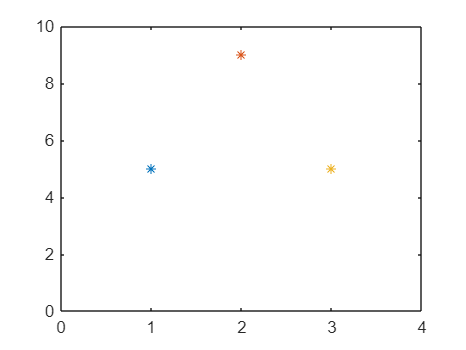

r1 = day1to10(1);
r2 = day1to10(1);
r3 = day1to10(1);
figure;
plot(1, r1, '*');
hold on;
plot(2, r2, '*');
plot(3, r3, '*');
axis([0 4 0 10]);
hold off;

3) What is the ensemble mean and variance of the process?

For a binomial distribution we know that the variance is sigma^2=npq

varbin = 10 * 0.5 * 0.5

varbin = 2.5000

We also know that the mean is E = n * p

meanbin = 10 * 0.5

meanbin = 5

4) What is the mean and variance of the process of one realisation?

5) Verify Question 3 and 4 with the Matlab function.

We try by running 30 realisations and see what the ensemble mean and variance is:

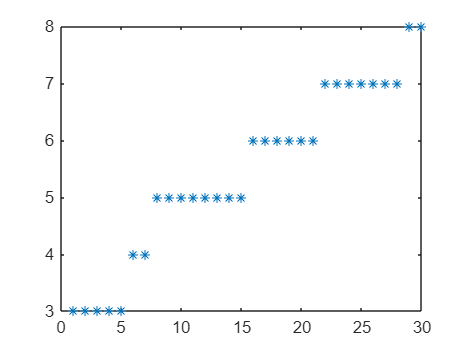

x = zeros(1, 30);
for i = 1:length(x)
    x(i) = day1to10();
end
x = sort(x);
figure;
plot(1:length(x), x, '*');

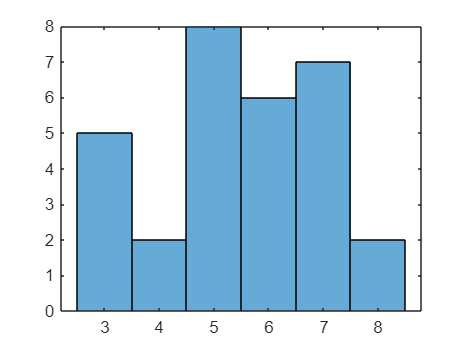

histogram(x)

ensmean = mean(x)

ensmean = 5.4667

ensvar = var(x)

ensvar = 2.3264

We can see that both the mean and the variance are moving towards the theoretical mean and variance.

real1 = day1to10();
realmean = mean(real1)

realmean = 6

realvar = var(real1)

realvar = 0

6) Is the process Y(n) Wide Sense Stationary (WSS), and is it ergodic?

Since that the Process Y(n) is independent of time we know that the ensemble mean and ensemble variance are both constant and therefore the process is WSS.

But when we take a single realization we can see that since it's only one value that the variance is 0 and the value is somewhere in the binomial distribution B(10, 0.5). So therefore the realisation variance is different from the ensemble variance and the realization mean is different from the ensemble mean. We can conclude that it is therefore not ergodic.

Process 2:

We now work with a scenario where patients die, are infected and are cured. Show three different versions of how an outbreak in the hospital can develop over 10 days if:

We define another random variable W(n) that is a discretely uniformly distributed, and can take the values {-2,  -1, 0, 1, 2}. The variables in W are independent and identically distributed (i.i.d.).

Day 1: Number of infected patients is X plus a random variable W(1)

Day 2: Number of infected patients is X plus a random variable W(2)

Day n: Number of infected patients is X plus a random variable W(n).

This is a stochastic process, we can write a

1) Make a matlab function that generates realizations of the process Y(n).

day10to20 = @(n)day1to10()+randi([-2 2]);

2) Plot three realizations of the process.

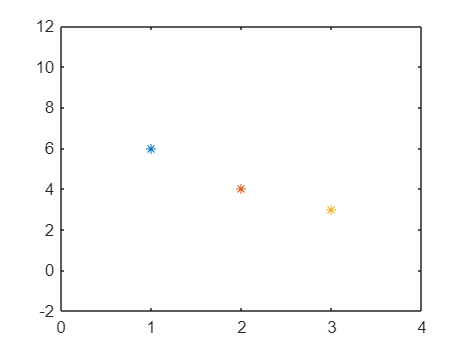

r1 = day10to20();
r2  = day10to20();
r3 = day10to20();

figure;
plot(1, r1, '*');
hold on;
plot(2, r2, '*');
plot(3, r3, '*');
axis([0 4 -2 12]);
hold off;

3) What is the ensemble mean and variance of the process?

Because W(n) is symmetrical and has a mean of 0 by linearity the mean is therefore kept at 5

ensmean10to20 = meanbin + 0

ensmean10to20 = 5

The variance is also linear so we can add the 2 variances together. We know the previous variance of X is 2.5. Since W(n) is a uniformly distributed function we can use the following to calculate the variance

univar = ((2-(-2)+1)^2-1)/12

univar = 2

ensvar10to20 = varbin + univar

ensvar10to20 = 4.5000

4) What is the mean and variance of the process of one realization?

The realisation mean is binomial distribution (10, 0.5) + Uniform distribution(-2, 2)

By linearity the variance of the realisation is var(Y(n)) = var(X) + var(W(n))

The variance of X is 0 since X is constant.

The variance of the uniform distribution = 2 as we calculated before which means the realisation variance is 2.

5) Verify Question 3 and 4 with the Matlab function.

6) Is the process Y(n) Wide Sense Stationary (WSS), and is it ergodic?

Since the process still is independent from time then the mean and variance will remain constant and is therefore WSS.

The process is still not ergodic since our ensemble mean isnt always the realisation mean.

Process 3: